Optimization Techniques1 

clc;
clear;
close;
clearvars;
clearAllMemoizedCaches;
e = 0.0005

e = 5.0000e-04

l = 0.01

l = 0.0100

a = -1

a = -1

b = 3

b = 3

gamma = 0.618

gamma = 0.6180

range = [a b]

range =     -1     3


itter = 20

itter = 20

syms ff1(x) ff2(x) ff3(x);

%symbolic notation

ff1(x) = (x-2)^2 + x*log(x+3)

$$ff1(x) = x\,\log\left(x+3\right)+{\left(x-2\right)}^{2}$$

ff2(x) = 5^x+(2-cos(x))^2

$$ff2(x) = {\left(\cos\left(x\right)-2\right)}^{2}+5^{x}$$

ff3(x) = (exp(x))*(x^3-1) + (x-1)*sin(x)

$$ff3(x) = \sin\left(x\right)\,\left(x-1\right)+{\mathrm{e}}^{x}\,\left(x^{3}-1\right)$$

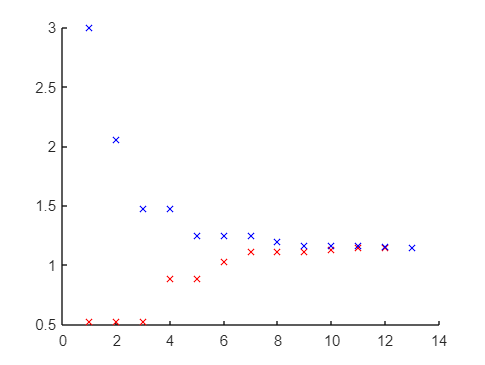

lll = 1.1443

llll = 1.1508

kkkk = 15


%dff1 = diff(ff1,x)
%anonymous function for easy handling
f1 = matlabFunction(ff1);
f2 = matlabFunction(ff2);
f3 = matlabFunction(ff3);

%another way to initialize
%f1 = @(x) (x-2)^2 + x*log(x+3)
%f2 = @(x) 5^x+(2-cos(x))^2
%f3 = @(x) (exp(x))*(x^3-1) + (x-1)*sin(x)

%for plotting the functions
% fplot(f1,range)
% fplot(f2,range)
% fplot(f3,range)

%Plotting for Dichotomous search only
%Plot_a(f3,a,b,itter)
% Plot_a(f2,a,b,itter)
% Plot_a(f3,a,b,itter)

%Handles
func1 = @Dichotom;
func2 = @GoldenSec;
func3 = @FibMeth;
func4 = @Dichotom_grad;

%----Plotting [k,l],[a,b,l] ------------------------%
%Dichotomous search :
%Plot_b(f1,a,b,itter,func1,2)
%Plot_b(f2,a,b,itter,func1,2)
%Plot_b(f3,a,b,itter,func1,2)

%Golden section search [k,l],[a,b,l]:
% Plot_b(f1,a,b,itter,func2,1)
% Plot_b(f2,a,b,itter,func2,1)
% Plot_b(f3,a,b,itter,func2,1)

%Fibonacci search ..:
% Plot_b(f1,a,b,itter,func3,1)
% Plot_b(f2,a,b,itter,func3,1)
% Plot_b(f3,a,b,itter,func3,1)

%Dichotomous search ..:
% Plot_b(ff1,a,b,itter,func4,1)
% Plot_b(ff2,a,b,itter,func4,1)
% Plot_b(ff3,a,b,itter,func4,1)
%--------------------------------------------------%


%For the algorithms(if you also want to plot (k,a) and (k,b) there are
%comments inside each function).

%Dichotomous search:
% [c,d,kappa0] = Dichotom(f1,a,b,e,l,itter)
% [id1,id2] = Dichotom(f2,a,b,e,l,itter)
% [id31,id32] = Dichotom(f3,a,b,e,l,itter)

%Golden section search:
% [id33,id34,kappa] = GoldenSec(f1,a,b,e,l,itter,0.618)
% [id44,id45,kappa1] = GoldenSec(f2,a,b,e,l,itter,0.618)
% [id38,id39,kappa2] = GoldenSec(f3,a,b,e,l,itter,0.618)

%Fibonacci search method:
% [lll,llll,kkkk] = FibMeth(f1,a,b,e,l,itter)

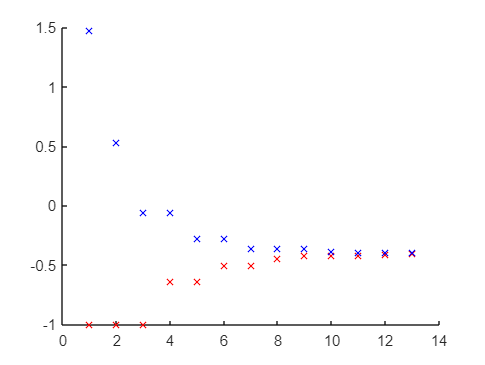

lll1 = -0.4033

llll2 = -0.3967

kkkk3 = 15

% [lll1,llll2,kkkk3] = FibMeth(f2,a,b,e,l,itter)

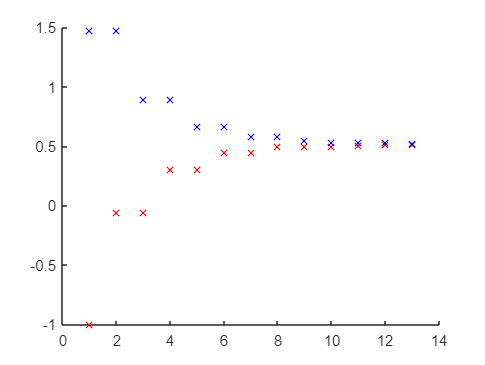

lll21 = 0.5148

llll22 = 0.5213

kkkk23 = 15

% [lll21,llll22,kkkk23] = FibMeth(f3,a,b,e,l,itter)


%Bisection with derivative:
% [oo,ooo,oooo]  = Dichotom_grad(ff1,a,b,e,l,itter)
% [o1o,o1oo,o1ooo]  = Dichotom_grad(ff2,a,b,e,l,itter)
% [o4o,o4oo,oo4oo]  = Dichotom_grad(ff3,a,b,e,l,itter)







Mέθοδος Διχοτόμου:

function [a,b,k] = Dichotom(f,a,b,e,l,itter,~)
%by uncommenting-> for plotting (k,a) (k,b)

%ceiling of iterations: 
%itter = ceil(log(4/l)/log(2));

% figure;       
% hold on;
k=1;
x1 = a;
x2 = b;

while (b - a) > l  % && (k<itter)
    
    x1 = (a+ b)/2 - e;
    x2 = (a+b)/2 + e;

    if f(x1) < f(x2)
        
        b = x2;
        
    else 
        a = x1;
       
        
        
    end
%     plot(k,a,'rx')
%     plot(k,b,'bx')
    
 k = k+1;   
end
k=k-1;
end

Μέθοδος Χρυσού Τομέα:

function [a,b,k] = GoldenSec(f,a,b,e,l,itter,gamma)
%uncommenting for (k,a) (k,b)

%itter = 

% figure;
% hold on;
    k=1;
    x1 = a + (1-gamma)*(b-a);
    x2 = a + gamma*(b-a);
    fx1 = f(x1);
    fx2 = f(x2);
    

    while (abs(b-a)>l) && (k<itter)
        
        
        if fx1 > fx2
            a = x1;
            
            x1 = x2;
            x2 = a + gamma*(b-a);

            
            fx1 = fx2;
            fx2 = f(x2);
            
            %plot(x1,fx1,'rx') %(x1,fx1)
             %plot(x2,fx2,'bo')
        else
            
            b = x2;
            x2 = x1;
            x1 = a + (1-gamma)*(b-a);
            
            
            fx2 = fx1;
            fx1 = f(x1);
            
            %plot(x1,fx1,'gx')
            %plot(x2,fx2,'go')

        end
%         plot(k,a,'rx')   %uncomment this one
%         plot(k,b,'bx')
        k = k+1;
        
    end
    k = k+1;
end

Μέθοδος Fibonacci:

function [a,b,itter] = FibMeth(f,a,b,e,l,itter,~)
%uncommenting for (k,a) (k,b)

% figure;
% hold on;
    k=1;
    if l==0 
        fprintf("Dividing by Zero: Terminating")
    else
    tmp = (b-a)/l;
    %assuming lmin = 0.0001 tmpmax = 40000 and fibonacci(30)=832040
    %if we want smaller l we may want to consider bigger n0

    n0 = 1:30;
    n = fibonacci(n0); %n is the array with possible n
    itter = find(n>tmp, 1 ); %itter is the actual n described in 5.1
    Fn = n(itter);

    x1 = a + n(itter-2)*(b-a)/Fn;
    x2 = a + n(itter-1)*(b-a)/Fn;
    fx1 = f(x1);
    fx2 = f(x2);

    while(k < itter-2)
        
        if fx1 > fx2
            a = x1;
            x1 = x2;
            x2 = a + ((n(itter-k-1))*(b-a))/(n(itter-k));
            fx1 = fx2;
            fx2 = f(x2);
        else
            b = x2;
            x2 = x1;
            x1 = a + ((n(itter-k-2))*(b-a))/(n(itter-k));
            fx2 = fx1;
            fx1 = f(x1);
        end
%         plot(k,a,'rx')
%         plot(k,b,'bx')
        k = k+1;
        
        
    end
    x2 = x1+e;
   % k=k-1;
    if fx1 > f(x2) 
        a = x1;
    else
        b = x1;
    
    end
%     plot(k,a,'rx')
%     plot(k,b,'bx')
    end
end

Mέθοδος Διχοτόμου με παραγώγους:

function [a,b,k] = Dichotom_grad(f,a,b,e,l,itter,~)
%uncommenting for (k,a) (k,b)

%     figure;
%     hold on;
    f = diff(f);
    tmp = log(l/(b-a));
    k = 1;
    itter = round(tmp/log(1/2));

    
    while k < itter 
        x = (a+b)/2;
        tmp = eval(subs(f,x));
        if tmp == 0
            break;
        elseif tmp > 0
            b = x;
        else 
            a = x;
        
        end
%         plot(k,a,'rx')
%         plot(k,b,'bx')
        k = k+1;
        
    end
    k=k-1;
end
    

Functions for plotting:

function Plot_a(f,a,b,itter)
%this could work for either e or l 
    
    l = 0.01
    kappa = [];
    epsilon = [];
    alpha = [];
    beta = [];

    
    for e = 0.0049:-0.0001:0.00001
    
    
    [a1,b1,k1] = Dichotom(f,a,b,e,l,itter);
    kappa(end+1) = k1;
    epsilon(end+1) = e;
    alpha(end+1) = a1;
    beta(end+1) = b1;
    
    end
    TYRONOSAUR = 1
%    flip(epsilon)

%    flip(kappa)
    kappa = kappa*2 
    figure;
    plot(epsilon,kappa)
    figure;
    plot(epsilon,alpha)
    hold on;
    plot(epsilon,beta)


end

plot 

function Plot_b(f,a,b,itter,func,calls)
    %plotting relations between l,a,b,k->f calls,with e const
    %calls is how many calls are happening inside every algorithm
    
    
    e = 0.001
    kappa = [];
    lamda = [];
    alpha = [];
    beta = [];

    
    for l = 0.1:-0.001:0.0021
    
    
    [a1,b1,k1] = func(f,a,b,e,l,itter,0.618);
    kappa(end+1) = calls*k1;
    lamda(end+1) = l;
    alpha(end+1) = a1;
    beta(end+1) = b1;

    
    end
    figure;
    
    plot(lamda,kappa)

    figure;
    plot(lamda,alpha)
    hold on;
    plot(lamda,beta)
    
    
    
    

end